# HDsort tutorial:

This tutorial begins with the explanation how to load data form the Mea1k chip and how to preprocess that such that it can be used by the spike-sorter. If you already have preprocessed data files, skip to chapter 3.

## **Chapter 0: Installation**

1. Copy the file `+hdsort/global_user_config.template` to `+hdsort/global_user_config.m` and modify it such that it contains the correct information.

2. In order to use the grid package, you must set the correct path names in the file `+hdsort/+grid/config.m`. Important variables to set: `c.home, c.tokenFilesFolder, c.localSortingPath, c.linuxSortingPath, c.commonFolderName`.

## **Chapter 1: Loading Mea1k-recording files**

Opening recording files (this file does not contain any meaningful data and is only thought as an illustration of the functions!):

rawFile = fullfile('.', 'Tutorial', 'file01.raw.h5')

rawFile = Tutorial/file01.raw.h5

RAW = hdsort.filewrapper.BELMEAFile(rawFile)

  106000x1024 BELMEAFile array with properties:

                        P: [1x1 struct]
                   h5info: [1x1 struct]
                   fileID: [1x1 H5ML.id]
                    nDims: 2
                     dims: [106000 1025]
                  maxDims: [-1 1025]
         connectedChannel: [1020x1 double]
                     bits: [18x2 int64]
            missingFrames: []
             chip_version: {'Mea1k'}
              chip_number: []
         software_version: {'20161003'}
        hardware_settings: [1x1 struct]
              dimAddChans: [106000 1]
                 dataSets: [1x1 struct]
                 fileName: 'Tutorial/file01.raw.h5'
                 file_idx: 1
                   parent: []
      bCovIsPrecalculated: 0
         derivedClassName: 'BELMEAFile'
         samplesPerSecond: 20000
           MultiElectrode: [1x1 hdsort.filewrapper.MultiElectrode]
       fullMultiEle

Copy chunks of data into memory:

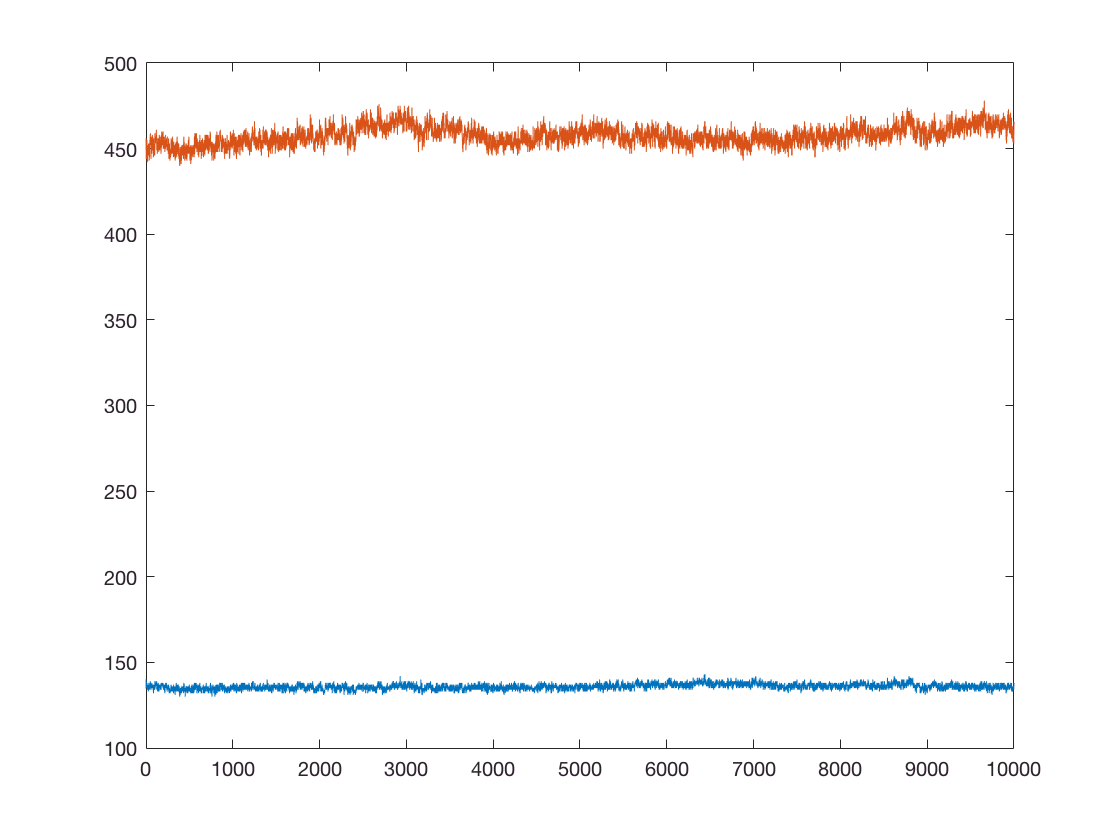

x = RAW(1:10000, 1:2);
figure; plot(x);

The file access can be restricted to a select set of channels:

RAW.restrictToChannels(1:4);
RAW.restrictToChannels(); % release restriction
RAW.restrictToConnectedChannels() % only those that were connected to an electrode

Get the electrode-channel configuration:

me = RAW.getMultiElectrode()

me =   MultiElectrode with properties:

    parentElectrodeIndex: [1020x1 double]
      electrodePositions: [1020x2 double]
        electrodeNumbers: [1020x1 double]
              dataSource: []
         electrodeLabels: []


epos = me.electrodePositions

epos =    1.0e+03 *

    1.7675    1.0150
    2.5025    1.3475
    1.6800    0.9625
    2.5550    1.3650
    1.6975    1.0150
    2.4325    1.3475
    1.6625    1.0500
    2.3975    1.3825
    1.6100    1.0325
    2.5725    1.3475


Get the frame numbers (i.e. time axis defined by the FPGA during the experiment):

frame_numbers = RAW.getFrameNumbers();
frame_numbers(1:10)'

ans =      5765568
     5765569
     5765570
     5765571
     5765572
     5765573
     5765574
     5765575
     5765576
     5765577


Get the hardware settings:

hws = RAW.getHardwareSettings()

hws =                 ADCStart: 6
                 ADCStop: 45
                   bias1: 8
                   bias2: 8
                   bias3: 3
                   bias4: 8
              biasoffset: 4
                    gain: 0
                gpioMode: 0
             init_time_s: 0
               midSupply: 128
                 probeIn: 0
                probeOut: 0
             probeOutBuf: 0
          reset_not_disc: 1
    reset_not_disc_value: 1
                  scmult: 0
                   stimH: 2820
                   stimL: 1304
                   stimM: 2048
               stimpower: 0
                   sw1_0: 1
                   sw1_1: 1
                   sw1_2: 0
                   sw1_3: 0
                   sw2_0: 1
                   sw2_1: 0
                   sw2_2: 0
                   sw2_3: 0
                   vRef1: 2048
                   vRef2: 2048
                   vRef3: 2048
                   vRef4: 2048
                vRefMosR: 1200
             vR

Get the time-stamp information (bits), usually for retina experiments:

bits = RAW.getBits();

## **Chapter 2: Preprocessing Mea1k-recording files**

Filter the raw file and save it in a format that is independent from the which chip type it was recorded. These files also only contain the channels that had been recording from connected electrodes.

This file format is larger than the original one because it is saved with more 'resolution'. Files saved in this format can be loaded in a similar way as the raw files above using the "`hdsort.filewrapper.CMOSMEA`" object. Multiple files that were recorded with the same configuration can be loaded at once and will be treated as one concatenated file.

Perform the preprocessing:

preprocessLocation = fullfile('.', 'Tutorial');
preprocessedFile = RAW.preprocessFile(preprocessLocation)

Creating File...
Processing 1/1 (  0% done)
Total: 
    0.0022

Done preprocessing.


preprocessedFile = ./Tutorial/file01.h5

preprocessedFiles = {preprocessedFile}

Use the grid infrastructure to preprocess many files:

sortingName = 'hd_sort_tutorial01';
rawFiles = {rawFile};
preprocessjob = hdsort.grid.PreprocessJob(sortingName, preprocessLocation, rawFiles, 'gridType', 'QSUB')

preprocessjob =   PreprocessJob with properties:

               preprocessJobP: [1x1 struct]
                oldMea1kFiles: 0
                     rawFiles: {'Tutorial/file01.raw.h5'}
                   gridConfig: [1x1 struct]
                      jobName: 'preprocess_hd_sort_tutorial01'
            allTaskParameters: []
                    logFolder: []
                        files: []
                      folders: [1x1 struct]
    m_nTasksCompletedLastTime: []
            m_tTimeLastChange: []
                 m_tTimeStart: []
                      taskIDs: 1
                     taskType: 'PreprocessJob'
                  memoryusage: []
                      runtime: [1x1 struct]
                   startIndex: 1
                     endIndex: 1
                     gridType: 'QSUB'
              nWorkersPerNode: 1
                            P: [1x1 struct]
                  P_untreated: [1x1 str

Note: You need to install this package on your grid before you can proceed. Check whether the grid engine uses 'qsub' or 'bsub' as submission commands. This tutorial ocurrently only supports linux.

Check if the preprocessing has not already happened:

preprocessjob.alreadyPreprocessed()

self =   106000x1020 CMOSMEA array with properties:

                    nFiles: 1
                 fileNames: {'./Tutorial/file01.h5'}
           fileWrapperList: [106000x1020 hdsort.filewrapper.CMOSMEAFile]
    fileWrapperClassHandle: []
             activeFileIdx: 1
            allFileLengths: []
          derivedClassName: 'CMOSMEA'
          samplesPerSecond: 20000
            MultiElectrode: [1x1 hdsort.filewrapper.MultiElectrode]
        fullMultiElectrode: []
            activeChannels: []
     memoryBufferNoiseSmad: []
                      info: 'This object is for loading many preprocessed CMOSMEA datafiles. The files are concatenated!'
                      name: 'CMOSMEA files'


ans =      1


Run the preprocessing if necessary:

if ~preprocessjob.alreadyPreprocessed()
    preprocessjob.setTaskParameters();
    preprocessjob.createAutoSubmitToken();
    all_tasks_completed = preprocessjob.waitForTasksToFinish(10);
end

self =   106000x1020 CMOSMEA array with properties:

                    nFiles: 1
                 fileNames: {'./Tutorial/file01.h5'}
           fileWrapperList: [106000x1020 hdsort.filewrapper.CMOSMEAFile]
    fileWrapperClassHandle: []
             activeFileIdx: 1
            allFileLengths: []
          derivedClassName: 'CMOSMEA'
          samplesPerSecond: 20000
            MultiElectrode: [1x1 hdsort.filewrapper.MultiElectrode]
        fullMultiElectrode: []
            activeChannels: []
     memoryBufferNoiseSmad: []
                      info: 'This object is for loading many preprocessed CMOSMEA datafiles. The files are concatenated!'
                      name: 'CMOSMEA files'


[preprocessedFiles, rawFiles, cmdFiles] = preprocessjob.getFileNames();

## **Chapter 3: Load preprocessed files**

Load preprocessed File:

PRE = hdsort.filewrapper.CMOSMEA(preprocessedFile);

self =   106000x1020 CMOSMEA array with properties:

                    nFiles: 1
                 fileNames: {'./Tutorial/file01.h5'}
           fileWrapperList: [106000x1020 hdsort.filewrapper.CMOSMEAFile]
    fileWrapperClassHandle: []
             activeFileIdx: 1
            allFileLengths: 106000
          derivedClassName: 'CMOSMEA'
          samplesPerSecond: 20000
            MultiElectrode: [1x1 hdsort.filewrapper.MultiElectrode]
        fullMultiElectrode: [1x1 hdsort.filewrapper.MultiElectrode]
            activeChannels: []
     memoryBufferNoiseSmad: []
                      info: 'This object is for loading many preprocessed CMOSMEA datafiles. The files are concatenated!'
                      name: 'CMOSMEA files'


Functions similar to the ones above:

PRE.restrictToChannels(1:4);
PRE.restrictToChannels();
x = PRE(1:10000, 1:2);

Detect spikes with a threshold (multiple of the noise std):

warning off
st = PRE.detectSpikes('thr', 5.0);

Detecting spikes...
Processing 1/2 (  0% done)


Processing 2/2 ( 50% done, est:    0 min:07 sec remaining):
Total: 
    6.3410



Done.
Elapsed time is 7.626486 seconds.


Cutting out spikes:

cutLeft = 20;
cutLength = 50;
vSpikes = PRE.getWaveform(st{1}, cutLeft, cutLength); % spikes in 2D format

get h5 matrix Waveform_ group close by (7)


tSpikes = hdsort.waveforms.v2t(vSpikes, PRE.getNChannels()); % spikes in 3D format

Plotting spikes:

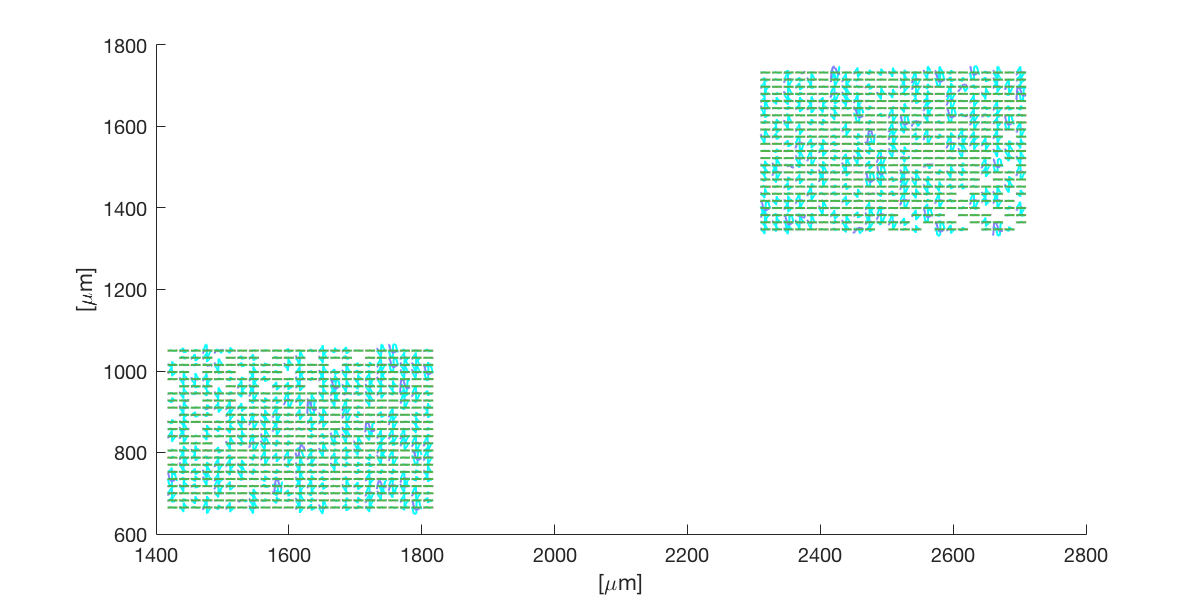

epos = PRE.MultiElectrode.electrodePositions;
hdsort.plot.Waveforms2D(tSpikes, epos);

Plotting spiketrains:

ans =   Rasterplot with properties:

                gdf: [12801x2 double]
             nUnits: 1010
            unitIds: [1x1010 double]
              Units: []
         timeToZero: 0
           interval: [2 105999]
           titleBox: []
            plotObj: []
           Children: {}
             Parent: []
           plotName: 'Rasterplot'
                 ah: [1x1 Axes]
                 fh: [1x1 Figure]
            hold_on: 1
              title: ''
                 Fs: 20000
               axis: []
             ylabel: ''
             xlabel: 'time [s]'
             legend: []
              XTick: [0 1 2 3 4 5 6]
              YTick: []
         XTickLabel: {7x1 cell}
         YTickLabel: []
          XTickMode: 'auto'
          YTickMode: 'manual'
     XTickLabelMode: 'auto'
     YTickLabelMode: 'manual'
             XScale: 'linear'
             YScale: 'linear'
               xlim: []
             

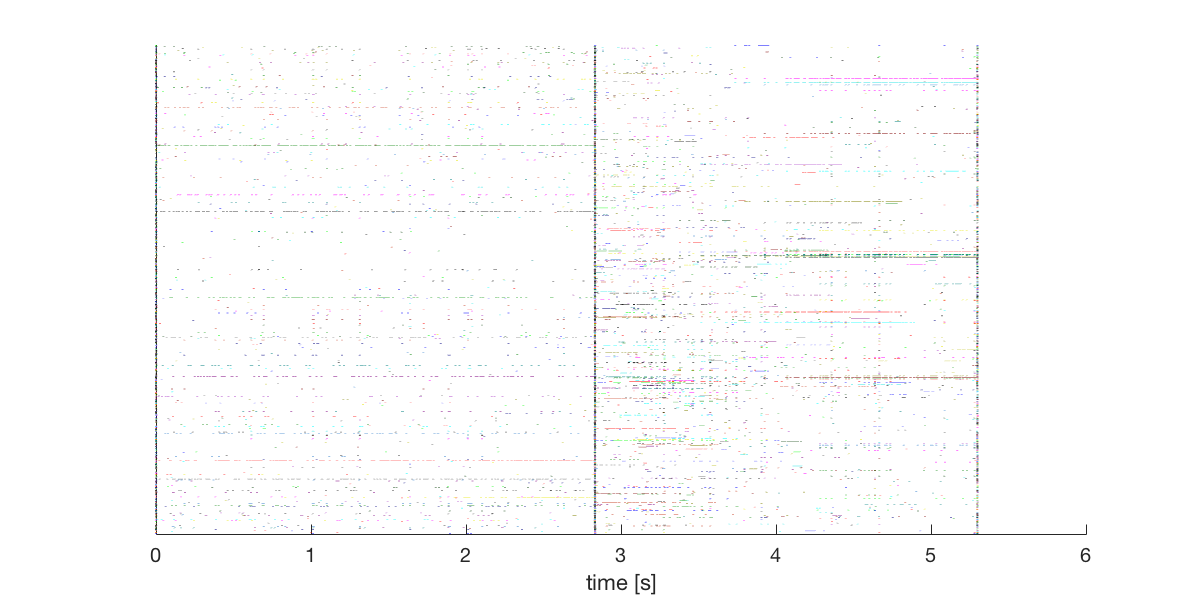

hdsort.plot.Rasterplot(st)

Number of samples in each input file:

nSamplesPerFile = PRE.getAllFileLength()

nSamplesPerFile = 106000

Estimate covariance matrix:

cov = PRE.getCovest()

## **Chapter 4: Sorting**

The sorting only works data that is already preprocessed (i.e. bandpassfiltered).

preprocessedFiles

preprocessedFiles =     './Tutorial/file01.h5'


PRE = hdsort.filewrapper.CMOSMEA(preprocessedFiles);

self =   106000x1020 CMOSMEA array with properties:

                    nFiles: 1
                 fileNames: {'./Tutorial/file01.h5'}
           fileWrapperList: [106000x1020 hdsort.filewrapper.CMOSMEAFile]
    fileWrapperClassHandle: []
             activeFileIdx: 1
            allFileLengths: []
          derivedClassName: 'CMOSMEA'
          samplesPerSecond: 20000
            MultiElectrode: [1x1 hdsort.filewrapper.MultiElectrode]
        fullMultiElectrode: []
            activeChannels: []
     memoryBufferNoiseSmad: []
                      info: 'This object is for loading many preprocessed CMOSMEA datafiles. The files are concatenated!'
                      name: 'CMOSMEA files'


If you do not yet have a file ready, you can create a generic matrix that is compatible with the spike-sorter:

M = randn(10000, 50);
PRE = hdsort.filewrapper.DataMatrix(M)

  10000x50 DataMatrix array with properties:

                        M: [10000x50 double]
         derivedClassName: 'DataMatrix'
         samplesPerSecond: 20000
           MultiElectrode: [1x1 hdsort.filewrapper.MultiElectrode]
       fullMultiElectrode: []
           activeChannels: []
    memoryBufferNoiseSmad: []
                     info: 'Wrapper for any data matrix that can then be used by the spike-sorter.'
                     name: 'DataMatrix'

       10000          50



Create a sorting object:

sortingName = 'hd_sort_tutorial01'

sortingName = hd_sort_tutorial01

sortingLocation =  fullfile('.', 'Tutorial');
sorting = hdsort.Sorting(PRE, sortingLocation, sortingName)

sorting =   Sorting with properties:

                DS: [10000x50 hdsort.filewrapper.DataMatrix]
             dPath: './Tutorial'
              name: 'hd_sort_tutorial01'
             files: [1x1 struct]
       filesLoaded: [1x1 struct]
       groupFolder: './Tutorial/sort_hd_sort_tutorial01/groups'
    groupFilesList: [13x1 containers.Map]
     maxElPerGroup: 9
           sortjob: []
    postprocessjob: []


When useing '`hdsort.filewrapper.DataMatrix`', you can only run the spike-sorter locally using the following command:

[R, P] = sorting.startSorting('sortingMode', 'localHDSorting')

Create groups...
Number of groups created: 39
Output directory does not exists. Trying to create... success.
Detecting spikes...
Detecting spikes...
Processing 1/1 (  0% done)
Total: 
    0.0015



Done.
Elapsed time is 0.029602 seconds.
Done.
Merging spikes trains...
1 spikes found total before merging
1 spikes after artefact removal (0 removed)
Done.
Found 1 spikes after merging.
Estimating Cov...
Done.
Cutting spikes...
+++++++++ERROR: MATLAB:imagesci:hdf5lib:fileOpenErr
Error using hdf5lib2
Unable to open file. Filename may be corrupt or have unsupported characters./Applications/MATLAB_R2016a.app/toolbox/matlab/imagesci/+H5F/open.m: 48
/Users/rolandd/Software/HDsort/+hdsort/+filewrapper/+hdf5/matrix.m: 237
/Users/rolandd/Software/HDsort/+hdsort/+filewrapper/+hdf5/matrix.m: 41
/Users/rolandd/Software/HDsort/+hdsort/sortScript.m: 367
/Users/rolandd/Software/HDsort/+hdsort/sortScript.m: 129
/Users/rolandd/Software/HDsort/+hdsort/startHDSorting.m: 81
/Users/rolandd/Software/HDsort/+hdsort/Sorting.m: 146
/private/tmp/tp949e214c_40d8_4e7b_bedb_b5e2ae30e1b1_liveeditor/Ma

Error using hdsort.leg.startHDSortingTemplateEstimation
Too many input arguments.

Error in hdsort.startHDSorting (line 84)
        hdsort.leg.startHDSortingTemplateEstimation(outPath, 'groups', ['group' sprintf('%04d', ii)], runName, Tf, cutleft, DSFull, groupsidx{ii}, MES);

Error in hdsort.Sorting/startSorting (

When using a file-based data object (such as '`hdsort.filewrapper.CMOSMEA`'), you can run it on a grid with:

[R, P] = sorting.startSorting('sortingMode', 'QSUB')

Alternatives are:

%sorting.startSorting('sortingMode', 'BSUB')
%sorting.startSorting('sortingMode', 'grid_for')
%sorting.startSorting('sortingMode', 'grid_parfor')

Run  the postprocessing also on the grid:

sorting.postprocessGridSorting()